## به نام خدا

# تمرین 3

# دینامیک سیالات محاسباتی

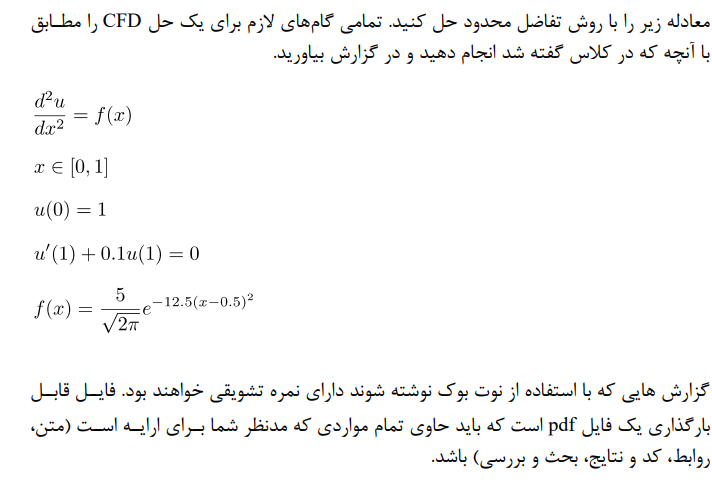

حل:

گام اول:تعریف معادله حاکم بر مسئله


$$\frac{d^2 u}{{\mathrm{dx}}^2 }=e^{-12\ldotp 5{\left(x-0\ldotp 5\right)}^2 }$$


گام دوم: تعریف دامنه ی حل

دامنه ی حل یک بعدی به صورت زیر می باشد


$$x\in \left\lbrack 0,1\right\rbrack$$


گام سوم : تجزیه کردن دامنه حل ومعادلات

ناحیه حل با توجه به تعداد گره ھای مورد نظر بھ گام ھای ھم اندازه ی تجزیه می شود چون ناحیه ی حل یک بعدی می باشد انتخاب اندازه ی

گام متناسب به دقت مورد نیاز می باشد

اندازه ی گام با توجھ به تعداد گره ھا با کد زیر محاسبه می شوند

n=17;
h=1/(n-1)

h = 0.0625

گام چھارم:انتخاب روش عددی مناسب

در اینجا از روش اختلافات محدود مرکزی برای گره ھای داخلی و روش اختلافات محدود پیشرو و پسرو برای گره اول و اخر استفاده شده است

A=sym(zeros(size(n,n)));
for i=2:n-1
    for j=1:n
        if j==i-1 | j==i+1
           A(i,j)=1;
        elseif i==j
           A(i,j)=-2;
        else
           A(i,j)=0;
        end
    end
end
disp(A)

$$\left(\begin{array}{ccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 \end{array}\right)$$

در ابتدا یک ماتریس شامل تعداد سطر و ستون برابر با تعداد گره ھای ایجاد کردیم و سپس در حلقه ضرایب اختلاف محدود مرکزی برای

گره ھای داخلی را جایگذاری کردیم حال برای اعمال شرایط مرزی داریم

A(1,1)=1; %first boundray condition
for i=1:n %second boundray condition
    if i==n
       A(n,i)=(1+(0.1*h));
    elseif i==n-1
       A(n,i)=-1;
    else
       A(n,i)=0;
    end
end
disp(A)

$$\left(\begin{array}{ccccccccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -2 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1 & \frac{161}{160} \end{array}\right)$$

A=sparse(double( A))

A =    (1,1)       1.0000
   (2,1)       1.0000
   (2,2)      -2.0000
   (3,2)       1.0000
   (2,3)       1.0000
   (3,3)      -2.0000
   (4,3)       1.0000
   (3,4)       1.0000
   (4,4)      -2.0000
   (5,4)       1.0000
   (4,5)       1.0000
   (5,5)      -2.0000
   (6,5)       1.0000
   (5,6)       1.0000
   (6,6)      -2.0000
   (7,6)       1.0000
   (6,7)       1.0000
   (7,7)      -2.0000
   (8,7)       1.0000
   (7,8)       1.0000
   (8,8)      -2.0000
   (9,8)       1.0000
   (8,9)       1.0000
   (9,9)      -2.0000
  (10,9)       1.0000
   (9,10)      1.0000
  (10,10)     -2.0000
  (11,10)      1.0000
  (10,11)      1.0000
  (11,11)     -2.0000
  (12,11)      1.0000
  (11,12)      1.0000
  (12,12)     -2.0000
  (13,12)      1.0000
  (12,13)      1.0000
  (13,13)     -2.0000
  (14,13)      1.0000
  (13,14)      1.0000
  (14,14)     -2.0000
  (15,14)      1.0000
  (14,15)      1.0000
  (15,15)     -2.0000
  (16,15)      1.0000
  (15,16)      1.0000
  (16,16)     -2.0000
  (17,

در این خط از کد شرط مرزی اولیه را در ماتریس ضرایب جایگزاری کرده و شرط دوم به صورت زیر تجزیه شده است


$$\begin{array}{l}
\mathrm{u'}\left(1\right)+0\ldotp 1\text{ }u\left(1\right)=0\\
\frac{u_n -u_{n-1} }{h}+0\ldotp 1\frac{\text{ }u_n \ast h}{h}=0\text{ }\longrightarrow \text{ }\left(1+0\ldotp 1h\right)u_n -u_{n-1} =0
\end{array}$$


در نتیجھ گسسته سازی برای گره ی پایانی بدین شکل خواھد بود.در خط آخر ماتریس ضرایب از حالت سمبولیک منلب به حالت عددی تبدیل

شده اند تا به صورت ورودی به ماتریس تنک فرمت مناسب داشته باشند

خروجی این بخش ماتریس ضرایب به صورت ماتریس تنک می باشد

b=sym(zeros(size(n,1)));
b(1,1)=1; %from first boundray condition
for i=2:n
    if i<n
       b(i,1)=vpa(h^2*5/(2*pi)^0.5* exp(-12.5*(((i-1)*h)-0.5)^2));
    else
       b(n,1)=0;
   end
end
disp(b)

$$\left(\begin{array}{c} 1\\ 0.00071212564797250277846829558114905\\ 0.0013434819497400763994160444170234\\ 0.0022987697504750011397167686055809\\ 0.003567364949004334703092089498\\ 0.0050209747528659129378603154236771\\ 0.0064093939169995138571689352602334\\ 0.0074205196523169491412685871978283\\ 0.0077918414140904831283185316692652\\ 0.0074205196523169491412685871978283\\ 0.0064093939169995138571689352602334\\ 0.0050209747528659129378603154236771\\ 0.003567364949004334703092089498\\ 0.0022987697504750011397167686055809\\ 0.0013434819497400763994160444170234\\ 0.00071212564797250277846829558114905\\ 0 \end{array}\right)$$

در این مرحله از کد ماتریس معلومات تشکیل شده است که خط اول این ماتریس شرط مرزی اول بوده و برای گره ھای داخلی این مقدار از

تابع محاسبه می شود

گام پنجم:حل دستگاه معادلات عددی

حل دستگاه توسط کد زیر اجرا می شود

u=A\b

$$u = \left(\begin{array}{c} 1.0\\ 0.93576912928592634700507669652903\\ 0.87225038421982519678862168863922\\ 0.81007512110346412297158272516643\\ 0.75019862773757805029426053029921\\ 0.69388949932069631232003042493\\ 0.64260134565668048728366063498447\\ 0.59772258590966417610445978029916\\ 0.56026434581496481406652751281169\\ 0.53059794713435593515691377699348\\ 0.5083520681060640053885686283731\\ 0.49251558299477158947739241501296\\ 0.48170007263634508650407651707649\\ 0.47445192722692291823385270863802\\ 0.46950255156797575110334566880513\\ 0.46589665785876866037225467338927\\ 0.46300288979753407241963197355455 \end{array}\right)$$

با دستور بالا مقادیر مختلف تابع در گره ھای گسسته شده بدست می یاد

گام ششم:صحت سنجی

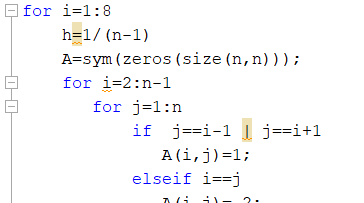

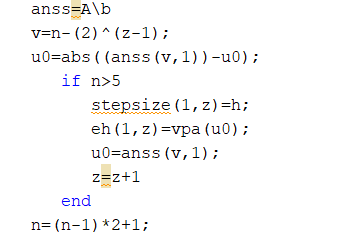

برای بررسی اعتبار نتایج کل کد در یک حلقه قرار گرفته شده که برای 8 دفعھ ی با اندازه گام ھای مختلف که ھر دفعھ اندازه ی گام کوچکتر

می شود نتایج بدست آمده با نتایج گام ھای بزرگ مقایسه می شود

اخلاف بین مقدار تابع در یک اندازه ی گام با مقدار تابع با اندازه گام بزرگ تر می دھد که نشانه ی دقت می باشد errorماتریس  

کل کد

n=33;
stepsize=[];
eh=sym(zeros(size(1,4)))

$$eh = 0$$

u0=0;
z=1;
for i=1:4
    h=1/(n-1)
    A=sym(zeros(size(n,n)));
    for i=2:n-1
       for j=1:n
           if  j==i-1 | j==i+1
              A(i,j)=1;
           elseif i==j
              A(i,j)=-2;
           else
              A(i,j)=0;
           end
       end
    end
    A(1,1)=1; %first boundray condition 
    for i=1:n %second boundray condition 
        if i==n
            A(n,i)=(1+(0.1*h));
        elseif i==n-1
            A(n,i)=-1;
        else 
            A(n,i)=0;
        end
    end
    A=sparse(double( A));
    b=sym(zeros(size(n,1)));
    b(1,1)=1; %from first boundray condition
    for i=2:n
        if i<n
           b(i,1)=vpa(h^2*5/(2*pi)^0.5* exp(-12.5*(((i-1)*h)-0.5)^2));
        else
           b(n,1)=0;
        end
    end
    u=A\b;
    v=n-(2)^(z-1);
    u0=abs((u(v,1))-u0);
       if n>33
          stepsize(1,z)=h;
          eh(1,z)=vpa(u0);
          u0=u(v,1);
          z=z+1;
       end
    n=(n-1)*2+1;
end

h = 0.0313

h = 0.0156

h = 0.0078

h = 0.0039

disp(eh)

$$\left(\begin{array}{ccc} 0.0014053265856363295057935486016453 & 0.00032103384119207548300070840474859 & 0.00015685055947890841694699564104791 \end{array}\right)$$

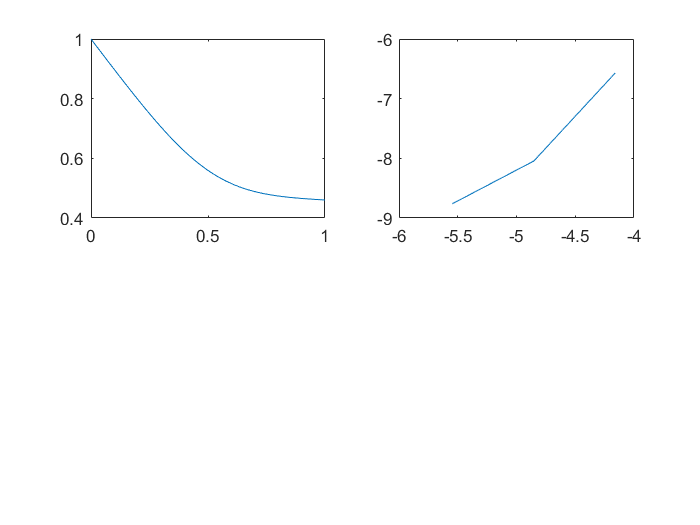

subplot(2,2,1);
plot((0:h:1),u); 
subplot(2,2,2);
plot(log(stepsize),log(eh))% numerical solution

s=(polyfit(log(stepsize),log(eh),1))

$$s = \left(\begin{array}{cc} 1.581721429408288480253032432484 & -0.11599529888665821415482971114359 \end{array}\right)$$

نتایج صحت سنجی

در اینجا شیب نمودار  لگاریتمی اروراست که تقریبا برابر با 2 می باشد s

با توجه به کد زیر حل دقیق معادله به شکل زیر است

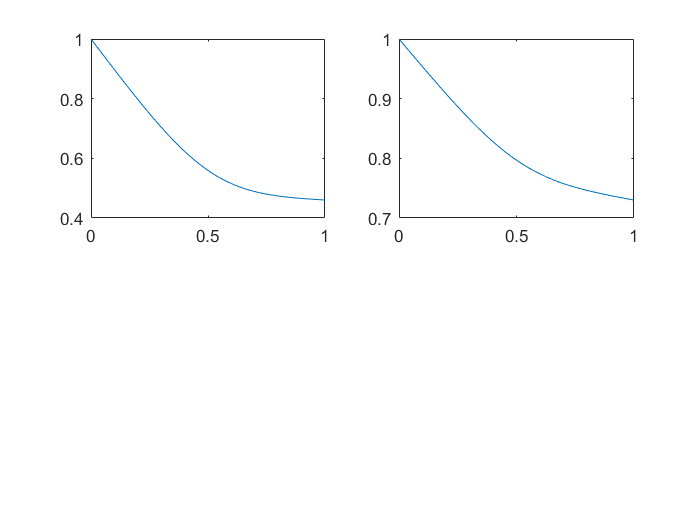

syms y(x) x;
Dy=diff(y,x);
exact=dsolve(diff(diff(y))==5/(2*pi)*(exp(-12.5*(x-0.5)^2)),y(0)==1,Dy(1)+(0.1*y(1))==0);
exact=matlabFunction(exact);
plot((0:0.001:1),exact(0:0.001:1))%exact solution

با توجه به اینکه با میل کردن اندازه ی گام به سمت صفر خطا متوالی نیز به سمت صفر میل می کند می توان گفت نتایج معتبر ھستند.همچنین از مقایسه ی  حل تحلیلی با حل عددی می توان به کد اعتبار بخشید در ادامه نمودار حل عددی وحل  تحلیلی آورده شده است

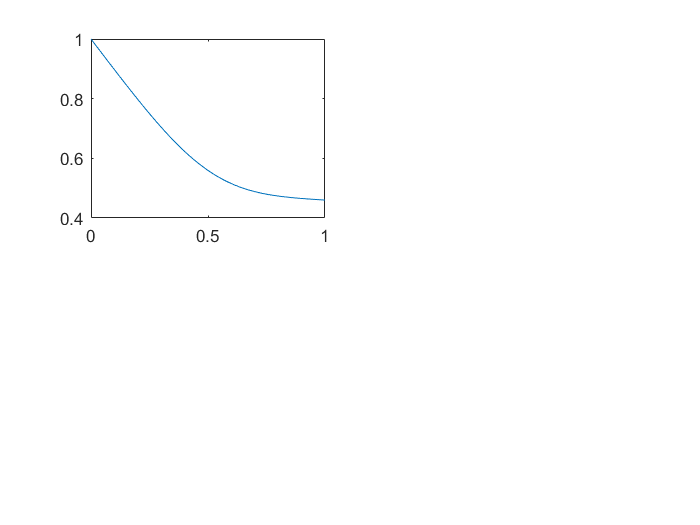

subplot(2,2,1);
plot((0:h:1),u)% numerical solution
plot((0:0.001:1),exact(0:0.001:1)) %exact solution

برای بدست آوردن خطای واقعی اختلاف تابع بدست آمده با مقدار دقیق تابع  به صورت زیر عمل میکنیم

n=33;
stepsize=[];
eh_exact=sym(zeros(size(1,4)));
z=1;
for i=1:4
    h=1/(n-1);
    A=sym(zeros(size(n,n)));
    for i=2:n-1
       for j=1:n
           if  j==i-1 | j==i+1
              A(i,j)=1;
           elseif i==j
              A(i,j)=-2;
           else
              A(i,j)=0;
           end
       end
    end
    A(1,1)=1; %first boundray condition 
    for i=1:n %second boundray condition 
        if i==n
            A(n,i)=(1+(0.1*h));
        elseif i==n-1
            A(n,i)=-1;
        else 
            A(n,i)=0;
        end
    end
    A=sparse(double( A));
    b=sym(zeros(size(n,1)));
    b(1,1)=1; %from first boundray condition
    for i=2:n
        if i<n
           b(i,1)=vpa(h^2*5/(2*pi)^0.5* exp(-12.5*(((i-1)*h)-0.5)^2));
        else
           b(n,1)=0;
        end
    end
    anss=A\b;
    v=n-(2)^(z-1);
    syms y(x) x;
    Dy=diff(y,x);
    exact=dsolve(diff(diff(y))==5/(2*pi)^0.5*(exp(-12.5*(x-0.5)^2)),y(0)==1,Dy(1)+(0.1*y(1))==0);
    exact=matlabFunction(exact);
    u0=abs((anss(v,1))-exact((v-1)*h));
    stepsize(1,z)=h;
    eh_exact(1,z)=vpa(u0);
    z=z+1;
    n=(n-1)*2+1;
end
disp(stepsize)

    0.0313    0.0156    0.0078    0.0039



disp(eh_exact)

$$\left(\begin{array}{cccc} 0.0012811470412494540642300024217577 & 0.00062180520359933763459665081881193 & 0.00030620292693699593104412768921038 & 0.00015192607066879241476416897745829 \end{array}\right)$$

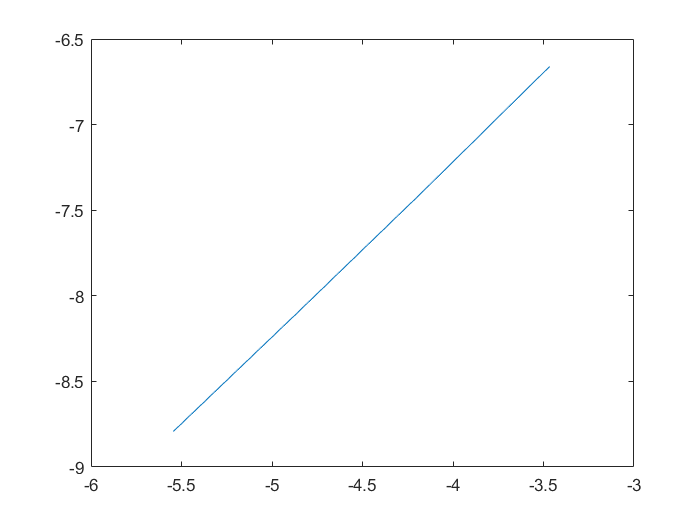

plot(log(stepsize),log(eh_exact))

s_exact=ceil(double(polyfit(log(stepsize),log(eh_exact),1)))

s_exact =      2    -3


در اینجا شیب نمودار  لگاریتمی ارور,واقعی است که برابر با 2 می باشد که با توجه به مرتبه دقت قطع درست می باشد و به حل اعتبار می بخشد s